# Half-wave rectification on the sine wave

In this program, we will demonstrate how to half-wave rectify a sine wave in the user-specified phase

clear;
clc;


Firstly generate a sine wave normally.

t = linspace(0, 3*pi, 500);
y = sin(t);

Then obtain the rectified half-wave

z1 = ((t < pi) | (t > 2*pi)).*y;

at the phase $\left(\frac{\pi }{3},\text{  }\frac{2\pi }{3}\right)\text{ }and\text{ }\left(\frac{7\pi }{3},\text{  }\frac{8\pi }{3}\right)$

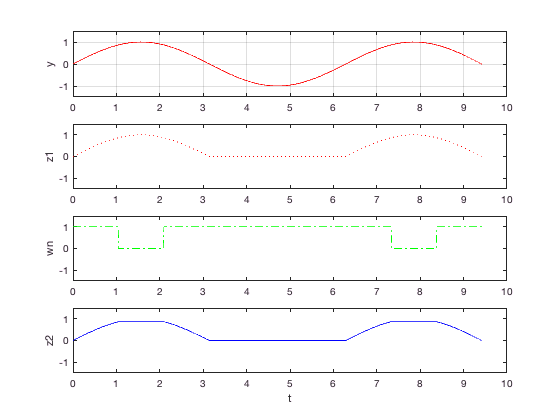

w = ((t > pi/3) & (t < 2*pi/3)) + ((t > 7*pi/3) & (t < 8*pi/3));
wn = ~w;
z2 = w*sin(pi/3) + wn.*z1;

% Plot these waveform in a figure.
subplot(4, 1, 1);
plot(t, y, 'r');
axis([0, 10, -1.5, 1.5]);
ylabel('y');
grid on;

subplot(4, 1, 2);
plot(t, z1, ':r');
axis([0, 10, -1.5, 1.5]);
ylabel('z1');

subplot(4, 1, 3);
plot(t, wn, '-.g');
axis([0, 10, -1.5, 1.5]);
ylabel('wn');

subplot(4, 1, 4);
plot(t, z2, '-b');
axis([0, 10, -1.5, 1.5]);
ylabel('z2');

xlabel('t');    % share the same x-axis